# **Controls the effect of time smoothing**

# 1. Load experiment

You can use this script as a standalone function. In this case, indicate the path to an extracted arboreal_scan folder, or to an arboreal_scan_experiment mat file here

path_to_use = 'C:\Users\Antoine.Valera\MATLAB\newextraction_raw_zscored\2019-10-01_exp_1';

You can use this script in a loop. To do this, 

- create a variable called use_existing and set it to true.

- create a loop with the exported experiment path called expe_folder. 

The expe_folder path can point to

- an extracted expe_folder, in this case the arboreal_scan_experiment object will be generated and saved. If expe_folder contains an exisiting arboreal_scan_experiment, the code will ask you want to do, which will pause the excution of the loop.

- an arboreal_scan_experiment object (faster)

if exist('use_existing','var') && use_existing == true && exist('expe_folder','var') && ischar(expe_folder)
    path_to_use = expe_folder
elseif exist('use_existing','var')
    error('to use this script in a loop, read the procedure explained in the code')    
end

obj = arboreal_scan_experiment(path_to_use);


if contains(path_to_use,'.mat')
    folder_to_use = parse_paths(fileparts(path_to_use));
else
    folder_to_use = path_to_use;
end


# 2. Define the Analysis Settings

## Arboreal Scan settings

obj.detrend                         = 0;            % -1; %'auto'
obj.rendering                       = 0;
obj.time_smoothing                      = [-1, 0];
obj.beh_smoothing                   = [-1, 0];
obj.detrend_behaviour               = false;

## Machine Learning settings

use_classifier  = false;                % true or false
method          = 'linear';             % 'linear' or 'svm'    
variable_type   = 'peaks_subtracted';   % 'peak_subtracted' or any other set of conditions / timepoints
behaviours      = {'encoder','EyeCam_L_forelimb','EyeCam_R_forelimb','BodyCam_L_whisker','BodyCam_R_whisker','EyeCam_Perioral','trigger','baseline'};
%behaviours      = {'encoder','BodyCam_L_whisker'}; 
N_iter          = 10;                   % N iterations
KFold           = 5; 
holdout         = 0;                    % percentage of data held out for final testing. If 0, we use KFoldLoss with custom Pearson coeff to estimate the score
rendering       = true;                    % If 0 no figure, if 1 summary plot is display per iteraton + averages, if 2, individual iteration data is displayed , if 3 hyperparameter optimization plot are displayed.


block_shuffle_size_s = 20

% For lag analysis, define the range and step size
time_step       = 0.25;
time_ext        = 5;
sr              = 1/nanmedian(obj.timescale.sr);
lag_list        = [(0:time_step:time_ext)*-1, (0:time_step:time_ext)];
lag_list        = unique(round(sort(lag_list) * sr))

# 3. Change Calcium smoothing during preprocessing

## On all ROIs

extracted_beh   = prepare_behaviour_data(obj, behaviours);
All_R           = {};
result          = {};
filter_list     = abs([0,-0.1,-0.5,-1,-2,-5,-10]);
for idx = 1:numel(filter_list)
    filter = filter_list(idx);
    obj.time_smoothing                      = filter; % 
    obj.process({'distance',50});       % will use obj.time_smoothing and obj.rendering
    obj.get_dimensionality([],'phate','peaks_subtracted',[]);
    obj.cluster_factors('dbscan',-5)
    
    ROI_selection       = [];
    [result{idx},~,~,All_R{idx}]      = predict_behaviours(obj, use_classifier ,... % true or false
                                                             method         ,... % 'linear' or 'svm'
                                                             variable_type  ,... % 'peak_subtracted' or any other set of conditions / timepoints
                                                             extracted_beh  ,... % Cell array of behaviours. add "_shuffled" to a behaviours name to shuffle timepoints
                                                             ROI_selection  ,... % Cell array of ROI to use as predictor. One cell = one predictor. When multiple value per cell, values are avergaed. If passing a list, then all ROIs are used individually
                                                             N_iter         ,... % N iterations
                                                             false          ,... % if ~false, random groups are generated matching "ROI_selection" size. If 1 we use all ROis, if -1 we only use ROIs not in ROI_selection
                                                             'optimize_hyper', true     ,... % ML varargin ; if true, Lambda is optimized for each iteration
                                                             'rendering', rendering     ,... % If 0 no figure, if 1 summary plot is display per iteraton + averages, if 2, individual iteration data is displayed , if 3 hyperparameter optimization plot are displayed.
                                                             'optimization_method', 'manual',... % "manual" or "native". Native uses MATLAB baysian search parameter optimization for Lambda. Native generate a search grid and find Lambda with the best prediction score.. 
                                                             'holdout', 0.2         ,... % percentage of data held out for final testing. If 0, we use KFoldLoss with custom Pearson coeff to estimate the score
                                                             'kfold', 1             ,...
                                                             'block_shuffling', ceil(20/nanmedian(diff(obj.t))),...
                                                             'title', ['Prediction on all behaviours, using modulation on all ROIs with a filter of ',num2str(abs(filter)),' s'],... % Bar chart title
                                                             'savefig',path_to_use);  % Save figure. If you set a path, the figure is saved there
end

bar_chart(result, '','','',cellfun(@(x) [num2str(x),' s'], num2cell(filter_list),'UniformOutput',false),true);
% save([folder_to_use, 'ML_All_ROIs'],'result','R','-v7.3')


# 4. Change Behaviour smoothing during preprocessing

## On all ROIs

% % Note : do not use prepare_behaviour_data in this loop
% obj.time_smoothing                      = 0 ; % Disable Ca2+ smoothing
% obj.process({'distance',50})            ;       % will use obj.time_smoothing and obj.rendering
% obj.get_dimensionality([],'phate','peaks_subtracted',[]);
% obj.cluster_factors('dbscan',-5)        ;
All_R                               = {};
result                              = {};
filter_list                         = [0,-0.1,-0.5,-1,-2,-5,-10];
for idx = 1:numel(filter_list)
    filter                      = filter_list(idx);
    obj.beh_smoothing           = [filter, 0]
    ROI_selection               = [];
    [result{idx},~,~,All_R{idx}]      = predict_behaviours(obj, use_classifier ,... % true or false
                                                             method         ,... % 'linear' or 'svm'
                                                             variable_type  ,... % 'peak_subtracted' or any other set of conditions / timepoints
                                                             behaviours     ,... % Cell array of behaviours. add "_shuffled" to a behaviours name to shuffle timepoints
                                                             ROI_selection  ,... % Cell array of ROI to use as predictor. One cell = one predictor. When multiple value per cell, values are avergaed. If passing a list, then all ROIs are used individually
                                                             N_iter         ,... % N iterations
                                                             false          ,... % if ~false, random groups are generated matching "ROI_selection" size. If 1 we use all ROis, if -1 we only use ROIs not in ROI_selection
                                                             'optimize_hyper', true     ,... % ML varargin ; if true, Lambda is optimized for each iteration
                                                             'rendering', rendering     ,... % If 0 no figure, if 1 summary plot is display per iteraton + averages, if 2, individual iteration data is displayed , if 3 hyperparameter optimization plot are displayed.
                                                             'optimization_method', 'manual',... % "manual" or "native". Native uses MATLAB baysian search parameter optimization for Lambda. Native generate a search grid and find Lambda with the best prediction score.. 
                                                             'holdout', 0.2         ,... % percentage of data held out for final testing. If 0, we use KFoldLoss with custom Pearson coeff to estimate the score
                                                             'kfold', 1             ,...
                                                             'block_shuffling', -20,...
                                                             'title', ['Prediction on all behaviours, using modulation on all ROIs with a behaviour filter of ',num2str(abs(filter)),' s'],... % Bar chart title
                                                             'savefig',path_to_use);  % Save figure. If you set a path, the figure is saved there
end

bar_chart(result, '','','',cellfun(@(x) [num2str(x),' s'], num2cell(filter_list),'UniformOutput',false),true);
% save([folder_to_use, 'ML_All_ROIs'],'result','R','-v7.3')

## 5.1. Time lag for all ROIs

obj = Using current obj.cc_mode : groups_peaks
  arboreal_scan_experiment with properties:

         extraction_method: 'median'
             source_folder: 'C:/Users/Antoine.Valera/MATLAB/newextraction_raw_zscored/2019-10-01_exp_1/'
             update_folder: ''
      extracted_data_paths: {1×30 cell}
               need_update: [1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1]
            arboreal_scans: {1×30 cell}
                 timescale: [1×1 struct]
                      demo: 0
        auto_save_analysis: 0
         auto_save_figures: 0
                filter_win: [0 0]
               filter_type: 'gaussian'
              dim_red_type: 'pca'
                  peak_thr: 2
               bad_ROI_thr: 0.2000
                   cc_mode: 'groups_peaks'
                   detrend: 0
              is_detrended: 1
               is_rescaled: 1
            default_handle: @(x)load_several_exp

lag_idx = 1

lag_idx = 2

lag_idx = 3

lag_idx = 4

lag_idx = 5

lag_idx = 6

lag_idx = 7

lag_idx = 8

lag_idx = 9

lag_idx = 10

lag_idx = 11

lag_idx = 12

lag_idx = 13

lag_idx = 14

lag_idx = 15

lag_idx = 16

lag_idx = 17

lag_idx = 18

lag_idx = 19

lag_idx = 20

lag_idx = 21

lag_idx = 22

lag_idx = 23

lag_idx = 24

lag_idx = 25

lag_idx = 26

lag_idx = 27

lag_idx = 28

lag_idx = 29

lag_idx = 30

lag_idx = 31

lag_idx = 32

lag_idx = 33

lag_idx = 34

lag_idx = 35

lag_idx = 36

lag_idx = 37

lag_idx = 38

lag_idx = 39

lag_idx = 40

lag_idx = 41

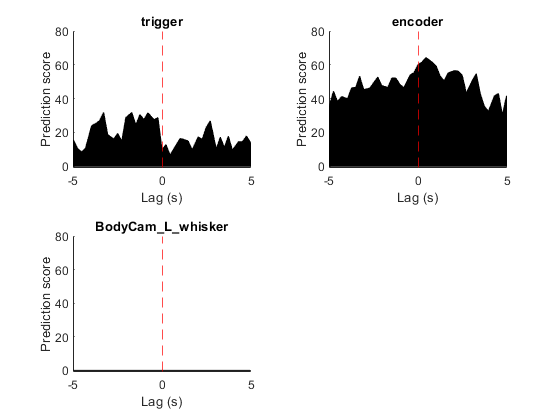

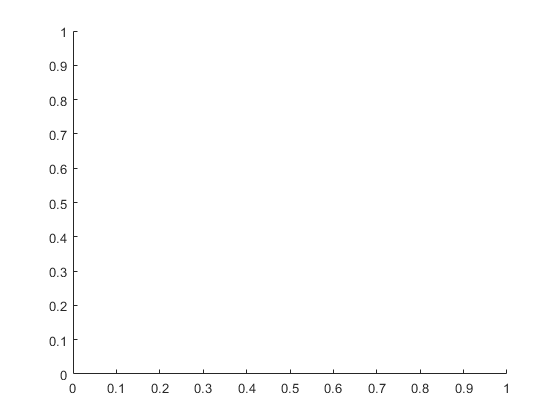

Error using matlab.graphics.axis.Axes/get
Operation terminated by the user.

Error in title (line 80)
   h = get(ax,'Title');


%% Run simulation for every lag value and different smoothing on behaviours
All_R                               = {};
result                              = {};
filter_list                         = [-2,-5,-10,-20];
behaviours = {'trigger','encoder','BodyCam_L_whisker'};
for idx = 1:numel(filter_list)
    filter                      = filter_list(idx);
    obj.beh_smoothing           = [filter, 0]
    ROI_selection               = [];
    
    % Extract behaours first to prevent doing it every time inside the for-loop
    %extracted_beh   = prepare_behaviour_data(obj, behaviours);
    extracted_beh   = prepare_behaviour_data(obj, behaviours);
    R               = {};
    close all
    
    for lag_idx = 1:numel(lag_list) 
        lag_idx
        lag = lag_list(lag_idx);
        [result_linear,~,~, R{lag_idx}]       = predict_behaviours(obj,use_classifier ,... % true or false
                                                                 method         ,... % 'linear' or 'svm'
                                                                 ['peaks_subtracted','_lag',num2str(lag)]       ,... % 'peak_subtracted' or any other set of conditions / timepoints
                                                                 extracted_beh  ,... % Cell array of behaviours. add "_shuffled" to a behaviours name to shuffle timepoints. Use prepare_behaviour_data(obj, behaviours) before predcit_behaviours if you call the function several times 
                                                                 ROI_selection  ,... % Cell array of ROI to use as predictor. One cell = one predictor. When multiple value per cell, values are avergaed. If passing a list, then all ROIs are used individually
                                                                 5              ,... % N iterations
                                                                 false          ,... % if ~false, random groups are generated matching "ROI_selection" size. If 1 we use all ROis, if -1 we only use ROIs not in ROI_selection
                                                                 'optimize_hyper', true     ,... % ML varargin ; if true, Lambda is optimized for each iteration
                                                                 'rendering', false     ,... % If 0 no figure, if 1 summary plot is display per iteraton + averages, if 2, individual iteration data is displayed , if 3 hyperparameter optimization plot are displayed.
                                                                 'optimization_method', 'manual',... % "manual" or "native". Native uses MATLAB baysian search parameter optimization for Lambda. Native generate a search grid and find Lambda with the best prediction score.. 
                                                                 'holdout', 0.2         ,... % percentage of data held out for final testing. If 0, we use KFoldLoss with custom Pearson coeff to estimate the score
                                                                 'block_shuffling', -20,...          ,...
                                                                 'title', ['Prediction on all behaviours, using modulation on all ROIs with a lag of ',num2str(lag/10),' s and smoothing of ',num2str(filter(1)), ' s',],... % Bar chart title
                                                                 'savefig',false);  % Save figure. If you set a path, the figure is saved there
    end
    
    All_R{idx} = R;
    
    %% Plot lag results
    a = cell2mat(R);x = lag_list/sr;
    f3 = figure();tiledlayout('flow');
    for beh = 1:numel(behaviours)
        axes(beh) = nexttile    ;  
        patch([x,fliplr(x)], [a(beh, :), zeros(size(a(beh, :)))], 'k');
        title(strrep(behaviours{beh},'_','\_'));xlabel('Lag (s)');ylabel('Prediction score');
        xline(0,'r--');
    end
    linkaxes(axes, 'xy')
    save_myfig(f3,[folder_to_use, 'All ROI groups with time lag and smoothing = ',num2str(filter(1))],{'png','pdf'})
    
    f5 = figure(2);clf();
    tiledlayout('flow');
    for beh = 1:size(extracted_beh.raw_behaviours, 1)
        axes(beh) = nexttile    ;
        title(strrep(extracted_beh.original_behaviour_list{beh},'_','\_'));hold on
        plot(linspace(min(x), max(x), max(lag_list)*2+1), xcorr(extracted_beh.raw_behaviours(beh,:),max(lag_list),'normalized')); hold on
        xlabel('Lag (s)');xline(0,'r--')
    end
    save_myfig(f5,[folder_to_use, 'behaviours crosscorrelation during full recording and smoothing = ',num2str(filter(1))],{'png','pdf'})
    
%     
%     [~,~,f6] = bar_chart(result, '','','',cellfun(@(x) [num2str(x),' s'], num2cell(filter_list),'UniformOutput',false),true);
%     save_myfig(f6,[folder_to_use, 'behaviours crosscorrelation during full recording and smoothing = ',num2str(filter(1))],{'png','pdf'})

end